**Guião 9**

1.

a)

%códigos = [10,0,11110,110,1110]
fprintf("1. a)")

1. a)

freq = [14,64,5,10,7];
bits = 14*2 + 64*1 + 5*5 + 10*3 + 7*4

bits = 175


prob = freq / sum(freq);
H = -sum(prob.*log2(prob))

H = 1.6260

b) O símbolo de menor ocorrência situa-se sempre à esquerda.

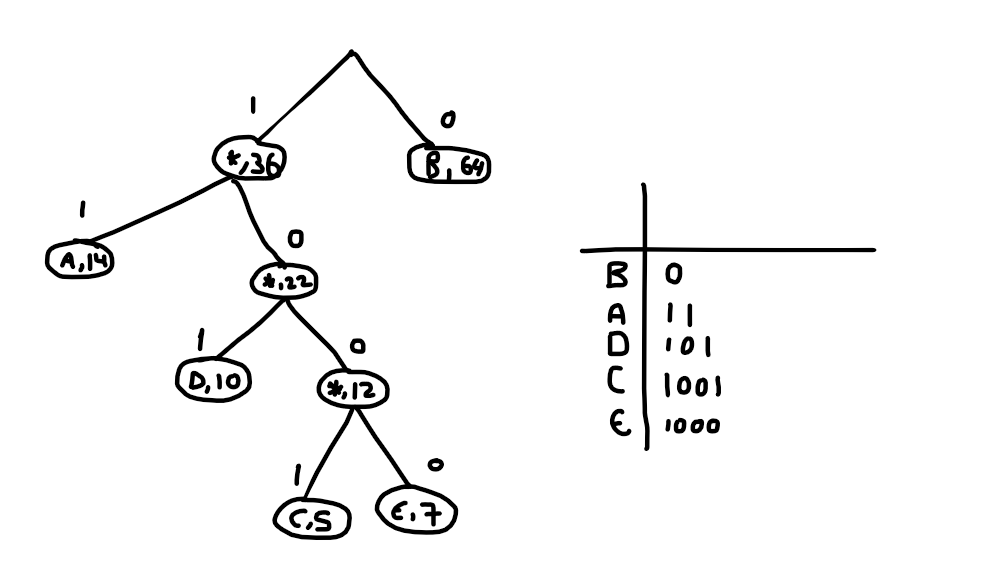

fprintf("b)")

b)

simbolos = 'ABCDE'

simbolos = 'ABCDE'

dicionario = huffmandict(1:5, prob)

dicionario = 5×2 cell array
    {[1]}    {[    1 1]}
    {[2]}    {[      0]}
    {[3]}    {[1 0 0 1]}
    {[4]}    {[  1 0 1]}
    {[5]}    {[1 0 0 0]}


input = randsrc(100,1,[1:5;prob]);
sequence = simbolos(input)

sequence = 'CDADBABBEEBEEBCBBDCEBADEBBBBBBBABAACBBEABBBCBBBBBBBBBBABEBBBBBBBDEBABBDBCBDBBBBBBDBBDBBBBBAABBEABBAB'

c) Entropia com 1000 símbolos?

2.

fprintf("2.")

2.


num_bits = cellfun(@length, dicionario(:, 2))';
numero_medio_por_simbolo = sum(num_bits .* prob);

[NumBits, NumBPS] = GeraMensagem(prob, 1000, num_bits)

NumBits = 1641

NumBPS = 1.6410

disp(NumBits)

        1641



não dá isto

3. 

a)

fprintf("3. a)")
prob = [0.2,0.05,0.25,0.15,0.35];

simbolos = 'A!LPO'
dicionario = huffmandict(1:5, prob)
input = randsrc(100,1,[1:5;prob]);
sequence = simbolos(input)

b)

fprintf("b)")
H = -sum(prob.*log2(prob))

c)

fprintf("c)")
message = 'OLA!';
c_dicionario = huffmandict(double(simbolos), prob);
c_encoded_message = huffmanenco(message, c_dicionario);
disp("Mensagem Codificada: ");
disp(c_encoded_message);

d)

fprintf("d)")
decoded_message = huffmandeco(c_encoded_message, c_dicionario);
disp("Mensagem descodificada: " + char(decoded_message));

4.

Árvore binária:

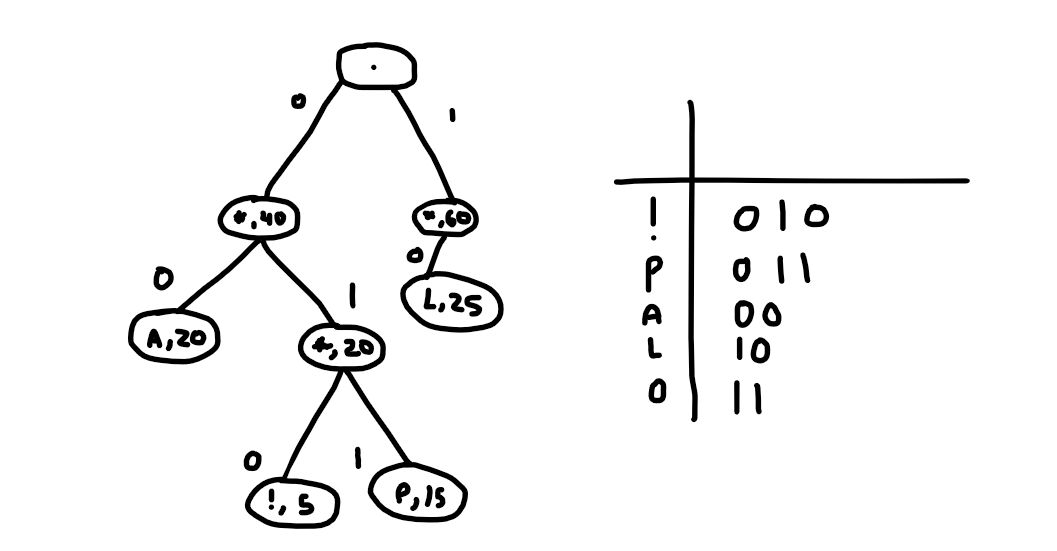

Codificação aritmética:

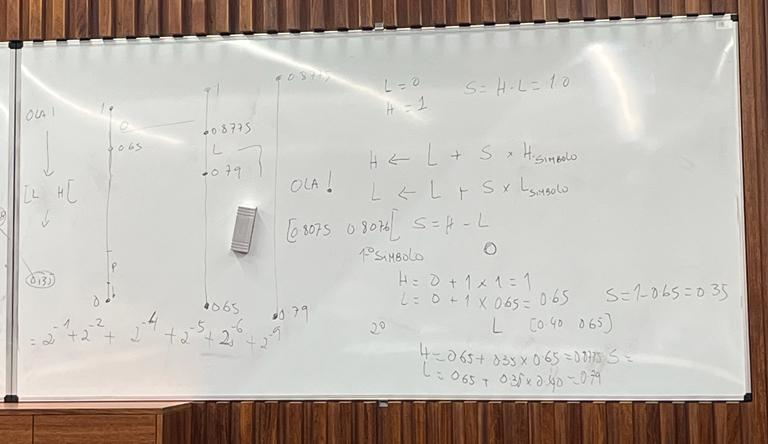

Função GeraMensagem:

function [NumBits, NumBPS] = GeraMensagem(f, CompMesg, nBits)
    % Utilizamos os índices dos símbolos como o alfabeto
    alfabeto = 1:length(f);
    % Geramos a mensagem aleatória como uma matriz (CompMesg x 1) que utiliza as probabilidades que nos foram passadas e o alfabeto que criamos.
    msg = randsrc(CompMesg, 1, [alfabeto; f]);

    NumBits = sum(nBits(msg));
    NumBPS = NumBits / CompMesg;
end

Função Alfabeto1:

function Simbolos = Alfabeto1(Texto)
    Simbolos = unique(Texto);
end

Função Alfabeto2:

function [Simbolos, Frequencia] = Alfabeto2(Texto)
   Simbolos = unique(Texto);
    for t= 1:length(Simbolos)
        Frequencia(t) =  count(Texto, Simbolos(t))/length(Texto);
        fprintf("%c aparece %f%s das vezes\n ", Simbolos(t), Frequencia(t)*100, "%");
    end
end